clear all;
close all;

% Load trained model and test data
fprintf('Loading trained model from "Data/final_model.mat"...\n');

Loading trained model from "Data/final_model.mat"...


load('../Data/final_model.mat', 'net');
fprintf('Trained model loaded successfully.\n');

Trained model loaded successfully.



fprintf('Loading test data from "Data/preprocessed_data.mat"...\n');

Loading test data from "Data/preprocessed_data.mat"...


load('../Data/preprocessed_data.mat', 'testInputs', 'testTargets');
fprintf('Test data loaded successfully.\n');

Test data loaded successfully.



% Perform predictions on the test data
fprintf('Predicting on the test data...\n');

Predicting on the test data...


predictedTestOutputs = net(testInputs);  % Raw outputs from network
predictedTestLabels = predictedTestOutputs >= 0.5;  % Convert to binary labels (assuming threshold of 0.5)

% Ensure both testTargets and predictedTestLabels are of type double
testTargets = double(testTargets);
predictedTestLabels = double(predictedTestLabels);

% Calculate accuracy
numCorrect = sum(predictedTestLabels == testTargets);
accuracy = numCorrect / length(testTargets) * 100;
fprintf('Accuracy on Test Data: %.2f%%\n', accuracy);

Accuracy on Test Data: 99.89%



% Save accuracy in a text file
metricsFile = fopen('../outputs/metrics.txt', 'w');
fprintf(metricsFile, 'Accuracy on Test Data: %.2f%%\n', accuracy);
fclose(metricsFile);

% Confusion Matrix
fprintf('Generating confusion matrix...\n');

Generating confusion matrix...


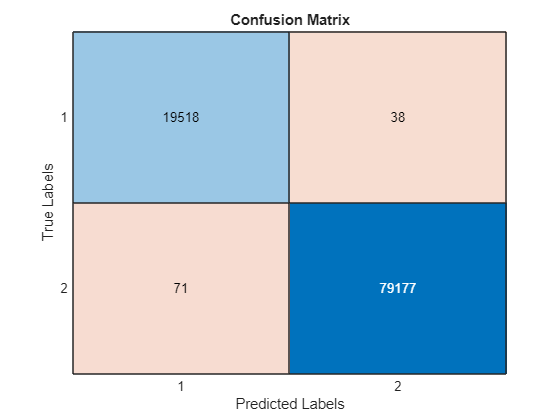

confMat = confusionmat(testTargets, predictedTestLabels);


% Display the confusion matrix using confusionchart
figure;
cm = confusionchart(confMat);

% Set properties to show numbers without scientific notation
cm.CellLabelFormat = '%d';  % Format labels as integers

% Customize the chart title and labels as needed
cm.Title = 'Confusion Matrix';
cm.XLabel = 'Predicted Labels';
cm.YLabel = 'True Labels';

% Save the confusion matrix plot as a high-resolution PNG file
exportgraphics(gcf, '../outputs/confusion_matrix.png', 'Resolution', 300);

fprintf('Confusion matrix saved as "../outputs/confusion_matrix.png" with high resolution.\n');

Confusion matrix saved as "../outputs/confusion_matrix.png" with high resolution.



% Calculate additional metrics (Precision, Recall, F1 Score)
truePositives = sum(predictedTestLabels == 1 & testTargets == 1);
trueNegatives = sum(predictedTestLabels == 0 & testTargets == 0);
falsePositives = sum(predictedTestLabels == 1 & testTargets == 0);
falseNegatives = sum(predictedTestLabels == 0 & testTargets == 1);

precision = truePositives / (truePositives + falsePositives);
recall = truePositives / (truePositives + falseNegatives);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 99.95%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 99.91%


fprintf('F1 Score: %.2f%%\n', f1Score * 100);

F1 Score: 99.93%



% Save additional metrics
metricsFile = fopen('../outputs/metrics.txt', 'a');  % Open in append mode
fprintf(metricsFile, 'Precision: %.2f%%\n', precision * 100);
fprintf(metricsFile, 'Recall: %.2f%%\n', recall * 100);
fprintf(metricsFile, 'F1 Score: %.2f%%\n', f1Score * 100);
fclose(metricsFile);

% ROC Curve and AUC
fprintf('Generating ROC curve...\n');

Generating ROC curve...


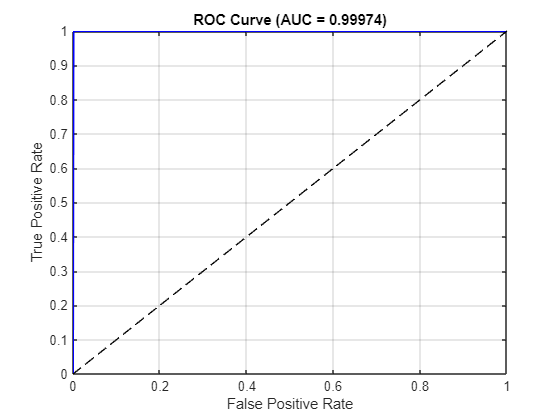

[X, Y, T, AUC] = perfcurve(testTargets, predictedTestOutputs, 1);
figure;
plot(X, Y, '-b', 'LineWidth', 1.5);
hold on;
plot([0 1], [0 1], '--k');  % Diagonal line for random guessing
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ', num2str(AUC), ')']);
grid on;
% Save the ROC curve as a high-resolution PNG file
exportgraphics(gcf, '../outputs/roc_curve.png', 'Resolution', 300);

fprintf('ROC curve saved as "../outputs/roc_curve.png" with high resolution.\n');

ROC curve saved as "../outputs/roc_curve.png" with high resolution.
